**Sobel Convolution**

% Membrane
javaaddpath('./');
import autopilot.interfaces.AutoPilotM;

%file_mem = 'X:/volume_scan/23-Apr-2018/nucleus_psf_488.tif';
file_mem = 'X:/volume_scan/04-May-2018/membrane_psf_561_endpoint.tif';
%file_mem = 'X:/volume_scan/04-May-2018/membrane_psf_561_tilted_ls.tif';
%file_mem = 'X:/volume_scan/04-May-2018/membrane_psf_561_0.387_4.55.tif';
best_focus_at = 28;
num_imgs_mem = numel(imfinfo(file_mem));
x_arr_mem = (1:1:num_imgs_mem);
y_arr_mem = zeros(1, num_imgs_mem);
raw_img = cell(num_imgs_mem);
for i = 1:num_imgs_mem
    raw_img{i} = imread(file_mem, i);
end

tic
y_arr_mem_ap = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = raw_img{i};
    %y_arr_mem_ap(i) = AutoPilotM.tenengrad2(filtered_img, 3);
    y_arr_mem_ap(i) = AutoPilotM.dcts2(filtered_img, 3);
end
toc

Elapsed time is 0.951953 seconds.


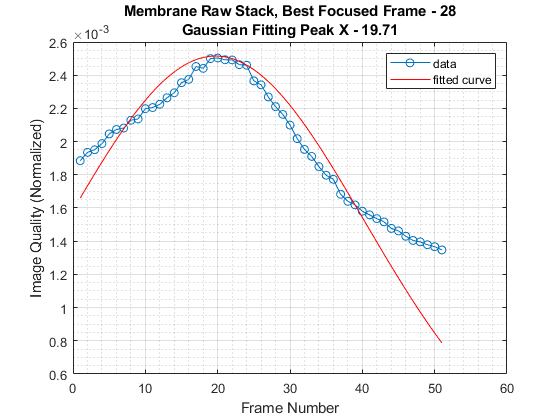

%y_arr_mem_ap = normalize(y_arr_mem_ap, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_ap', 'gauss1');
[peak_x_ap, peak_y_ap] = peak_in_gaussian(x_arr_mem, y_arr_mem_ap, '');

plot(f_mem, x_arr_mem, y_arr_mem_ap, '-o');
title(sprintf(['Membrane Raw Stack, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_ap));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

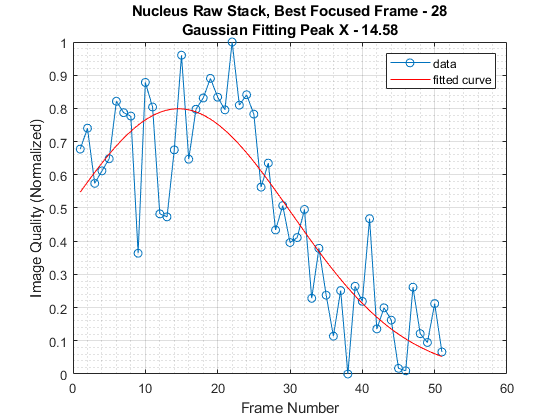



y_arr_mem_raw = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = raw_img{i};
    y_arr_mem_raw(i) = convolve_sobel(filtered_img);
end
y_arr_mem_raw = normalize(y_arr_mem_raw, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_raw', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_raw, '');


plot(f_mem, x_arr_mem, y_arr_mem_raw, '-o');
title(sprintf(['Nucleus Raw Stack, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

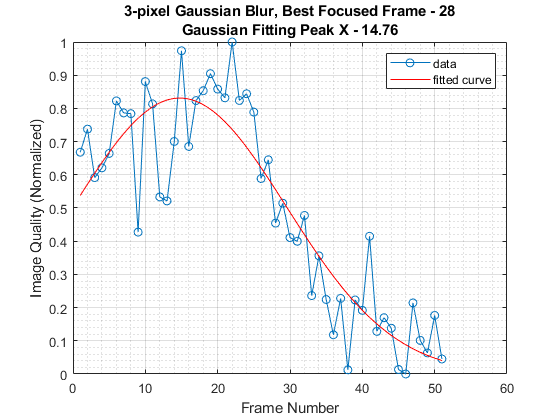




y_arr_mem_gau = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = imgaussfilt(raw_img{i},'FilterSize',3);
    y_arr_mem_gau(i) = convolve_sobel(filtered_img);
end
y_arr_mem_gau = normalize(y_arr_mem_gau, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_gau', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_gau, '');

plot(f_mem, x_arr_mem, y_arr_mem_gau, '-o');
title(sprintf(['3-pixel Gaussian Blur, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor



y_arr_mem_sub = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = imresize(imresize(raw_img{i},1/64,'box'),64,'box');
    y_arr_mem_sub(i) = convolve_sobel(filtered_img);
end
y_arr_mem_sub = normalize(y_arr_mem_sub, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_sub', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_sub, '');

-Gaussian fitting failed. Use max value instead.


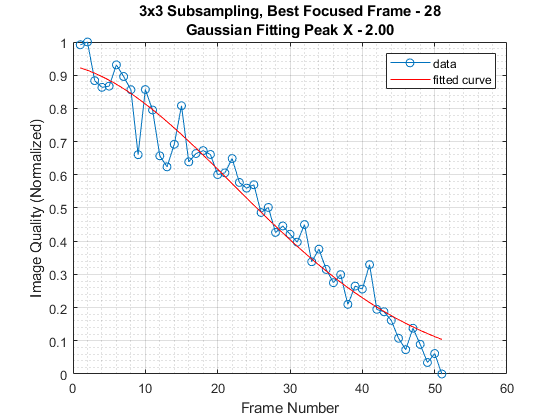


plot(f_mem, x_arr_mem, y_arr_mem_sub, '-o');
title(sprintf(['3x3 Subsampling, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

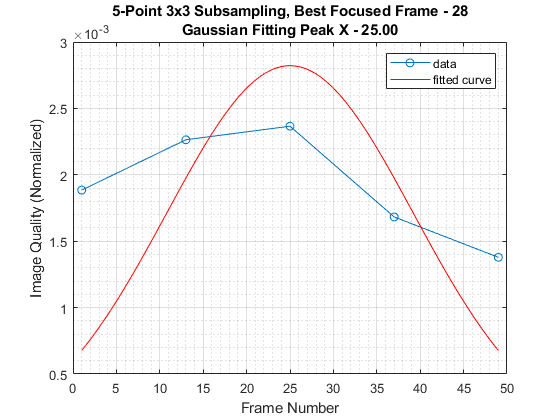


% ============ 5-point sampling ==============
x_arr_mem_raw = x_arr_mem(1:12:end);

y_arr_mem_ap = y_arr_mem_ap(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_ap', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_ap, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_ap, '-o');
title(sprintf(['5-Point 3x3 Subsampling, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

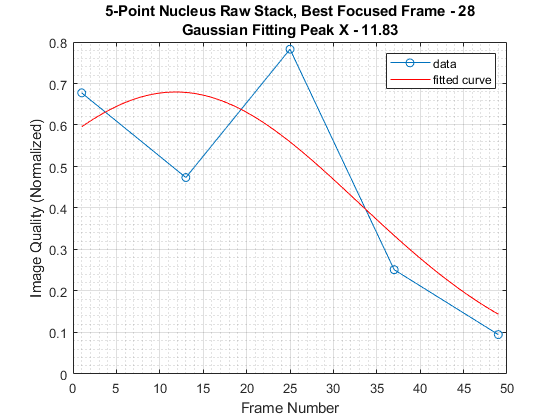


y_arr_mem_raw = y_arr_mem_raw(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_raw', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_raw, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_raw, '-o');
title(sprintf(['5-Point Nucleus Raw Stack, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

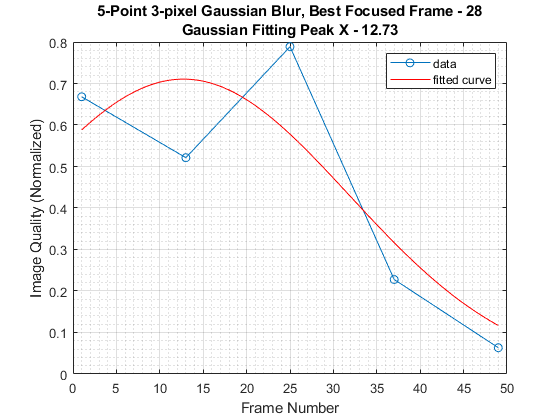


y_arr_mem_gau = y_arr_mem_gau(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_gau', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_gau, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_gau, '-o');
title(sprintf(['5-Point 3-pixel Gaussian Blur, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor


y_arr_mem_sub = y_arr_mem_sub(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_sub', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_sub, '');

-Gaussian fitting failed. Use max value instead.


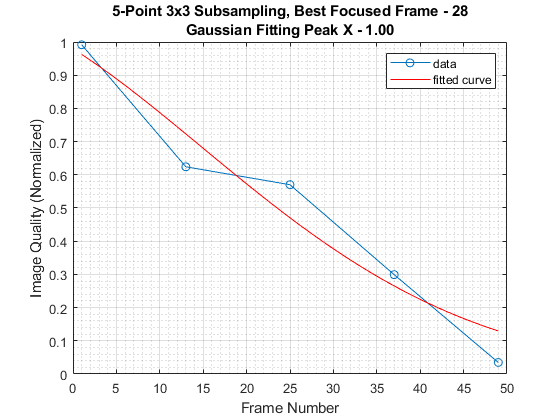

plot(f_mem, x_arr_mem_raw, y_arr_mem_sub, '-o');
title(sprintf(['5-Point 3x3 Subsampling, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor


% Nucleus
% disp('Nucleus');
% file_nuc = 'X:/volume_scan/23-Apr-2018/nucleus_psf_488.tif';
% num_imgs_nuc = numel(imfinfo(file_nuc));
% x_arr_nuc = (1:1:num_imgs_nuc);
% y_arr_nuc = zeros(1, num_imgs_nuc);
% for i = 1:num_imgs_nuc
%     raw_img = imread(file_nuc, i);
%     filtered_img = imgaussfilt(raw_img, 'FilterSize', 3);
%     %filtered_img = imresize(imresize(raw_img,0.5,'box'),2,'box');
%     y_arr_nuc(i) = convolve_sobel(filtered_img);
% end
% f = fit(x_arr_nuc', y_arr_nuc', 'gauss1');
% plot(f, x_arr_nuc, y_arr_nuc, '-o');
% 
% 
% [peak_x_nuc, peak_y_nuc] = peak_in_gaussian(x_arr_nuc, y_arr_nuc, '')



% file_mem = '\\nsrg.cs.unc.edu\nanodata2\Evan\180424 z stack of grid\10um grid_8\10um grid_8_MMStack_Pos0.ome.tif';
% num_imgs_mem = numel(imfinfo(file_mem));
% x_arr_mem = (1:1:num_imgs_mem);
% y_arr_mem = zeros(1, num_imgs_mem);
% for i = 1:num_imgs_mem
%     y_arr_mem(i) = -convolve_sobel((imread(file_mem, i)));
% end
% plot(x_arr_mem, y_arr_mem, '-o');
